Km = 0.3249

Km = 0.3249

Ke = 0.3249

Ke = 0.3249

J = 0.0016

J = 0.0016

R = 4.6808

R = 4.6808

L = 1.0411

L = 1.0411

W = tf(Km/J/L, [1 R/L Km*Ke/J/L])

W =
 
           195
  ---------------------
  s^2 + 4.496 s + 63.37
 
Continuous-time transfer function.



k = 1/Ke

k = 3.0779

T = sqrt(J*L/Km/Ke)

T = 0.1256

ksi = R/2*sqrt(J/Km/Ke)

ksi = 0.2881

% W1 = tf(Km/J/L*(J*L/Km/Ke), [1*(J*L/Km/Ke) R/L*(J*L/Km/Ke) Km*Ke/J/L*(J*L/Km/Ke)])
W1 = tf(k, [T^2 2*T*ksi 1])

W1 =
 
             3.078
  ---------------------------
  0.01578 s^2 + 0.07239 s + 1
 
Continuous-time transfer function.



% a0 = Km*Ke/J/L
% a1 = R/L
% p = [1 a1 a0]
% roots(p)
% syms w s t
% eps= R*sqrt(J/L/Km/Ke)
% achx
% afc = b/(sqrt(a^2+w^2))
% fplot(afc,[0,1000])
% % фчх
% pfc= atan(-w/a)
% fplot(pfc,[0,500])
% step(W)
% hold on
% step(W1)
% impulse(W1)
% hold on
% impulse(W)
lambda = ksi/T

lambda = 2.2937

omega = sqrt(1-ksi^2)/T

omega = 7.6229

syms t
% impl= k/omega/(T^2)*exp(-lambda*t)*sin(omega*t)
% fplot(impl,[0,3],"red")
% bode(W)
% step(W1)
% hold on
% st= k*(1-exp(-lambda*t)*(cos(omega*t) - lambda/omega * sin(omega*t)))
% fplot(st,[0,3],"red")

syms w
Wjw = (Km/J/L)/((1i*w)^2 + R/L*1i*w + Km*Ke/J/L)

$$Wjw = \frac{3431287367826553}{17592186044416\,\left(-w^{2}+\frac{46808\,w\,\mathrm{i}}{10411}+\frac{8918602126454777}{140737488355328}\right)}$$

real(Wjw)

$$ans = \frac{3431287367826553\,\mathrm{real}\left(\frac{1}{-w^{2}+\frac{46808\,w\,\mathrm{i}}{10411}+\frac{8918602126454777}{140737488355328}}\right)}{17592186044416}$$

imag(Wjw)

$$ans = \frac{3431287367826553\,\mathrm{imag}\left(\frac{1}{-w^{2}+\frac{46808\,w\,\mathrm{i}}{10411}+\frac{8918602126454777}{140737488355328}}\right)}{17592186044416}$$

A1=sqrt(real(Wjw)^2+imag(Wjw)^2)

$$A1 = \sqrt{\frac{11773733000606074423795091861809\,{\mathrm{imag}\left(\frac{1}{-w^{2}+\frac{46808\,w\,\mathrm{i}}{10411}+\frac{8918602126454777}{140737488355328}}\right)}^{2}}{309485009821345068724781056}+\frac{11773733000606074423795091861809\,{\mathrm{real}\left(\frac{1}{-w^{2}+\frac{46808\,w\,\mathrm{i}}{10411}+\frac{8918602126454777}{140737488355328}}\right)}^{2}}{309485009821345068724781056}}$$

F=atan2(imag(Wjw), real(Wjw))

$$F = \text{angle}\left(\mathrm{imag}\left(\frac{1}{-w^{2}+\frac{46808\,w\,\mathrm{i}}{10411}+\frac{8918602126454777}{140737488355328}}\right)\,\mathrm{i}+\mathrm{real}\left(\frac{1}{-w^{2}+\frac{46808\,w\,\mathrm{i}}{10411}+\frac{8918602126454777}{140737488355328}}\right)\right)$$

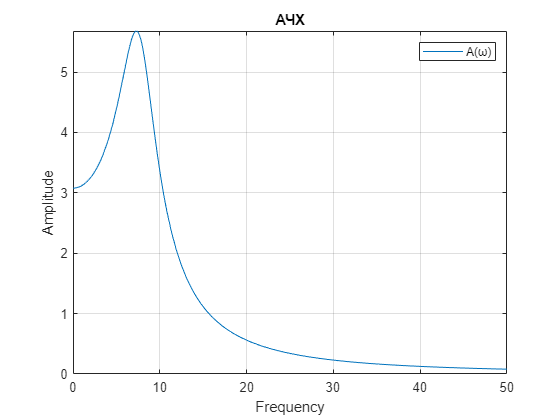

% ачх
fplot(A1,[0,50])
grid on
xlabel("Frequency")
ylabel("Amplitude")
title("АЧХ")
legend("A(ω)")

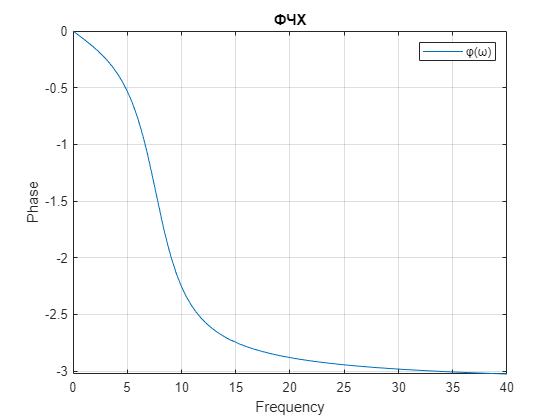


% фчх
fplot(F,[0,40])
grid on

xlabel("Frequency")
ylabel("Phase")
title("ФЧХ")
legend("φ(ω)")

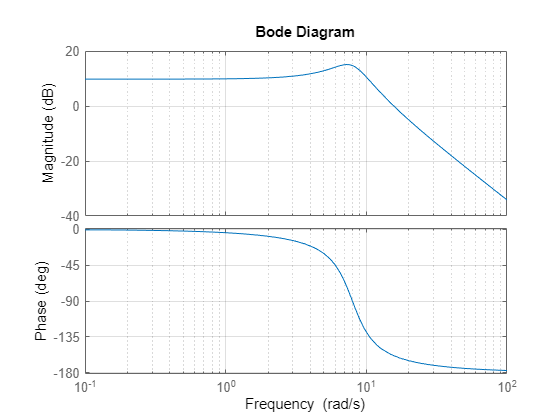

bode(W)
hold on
grid on